# Linear Control Design II - Group Work Problem Module 10

## Description

The suspension system is a key component of a vehicle directly affecting the passenger comfort and the ability of the vehicle itself to hold the road. In active suspension system an actuator is positioned between the sprung mass of the vehicle and the unsprung mass (wheel, tyre, brake, etc.) parallel to the suspension elements with the objective of pulling/pushing the vehicle body in order to suppress the vibrations due to road irregularities.

### Quarter-car suspension system

A simplified car suspension system is shown on the following figure

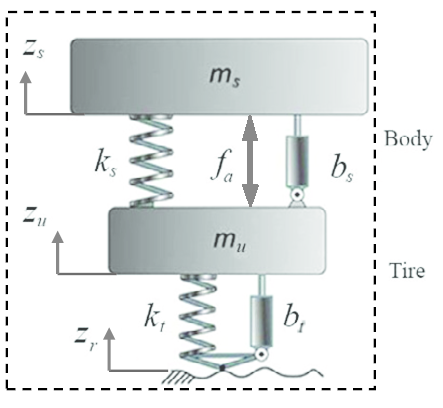

where

- $m_s, \, b_s, \, k_s$ are the mass, damping and stiffness of the sprung element (quarter-car)

- $m_u, \, b_t, \, k_t$ are the mass, damping and stiffness of the unsprung element (wheel-tyre-brake)

- $z_s$ is the displacement of the sprung element

- $z_u$ is the displacement of the unsprung element

- $z_r$ is the displacement of the road

- $f_a$ is the force exerted by an hydraulic actuator placed between the sprung and unsprung elements

The applied force on the tyre from the road 

$f_d =  b_t\dot{z}_r + k_tz_r$                                                               (1)

is considered as an unknown disturbance in the sytem, which should be properly handled by the active suspension.

The numerical values for the model parameters are provided right below.

% Model paramters (RG)
% Test the provided active suspension model on deterministic road profile (RG)
SIM_TIME = 100;
STEP_SIZE = 0.01; % integration step size of Simulink (can be changed as needed)
% System parameters
m_s = 243; % sprung mass [kg]
m_u = 40; % unsprung mass [kg]
b_s = 370; % damping coefficient [N*s/m]
b_t = 414; % tyre damping coefficient [N*s/m]
k_s = 14761; % stiffness coefficient [N/m]
k_t = 124660; % tyre stiffness coefficient [N/m]

### Open-loop system analysis

**Problem 1** Looking at the diagram of the quarter-car suspension and applying Newton's second law derive a state space model of the system. Identify state variables, control inputs and possible disturbances. Then compute the stationary state when the control input and the disturbnace are equal to zero.

**Solution** Applying Newton's second law two second order differential equations are derived that described the coupled dynamics of the sprung and unsprung masses, i.e.

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) + k_s(z_s-z_u) - f_a + b_t(\dot{z}_r-\dot{z}_u) + k_t(z_r-z_u)$          (2)

Using the definition of the unknown disturbance given in Eq. (1), then Eq. (2) can be rewritten as

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) - b_t\dot{z}_u+ k_s(z_s-z_u) - k_t z_u - f_a +f_d$           (3)

Given the model (3), the state vector is defined as $\mathbf{x} = [z_s, \dot{z}_s,z_u, \dot{z}_u]^\mathrm{T}$, the control input is the force exerted by the hydraulic actuator $f_a$, and the disturbance is applied force on the tyre $f_d$.

The state space model is then given by

% Your solutions goes here

A = [0 1 0 0; -k_s/m_s -b_s/m_s k_s/m_s b_s/m_s; ...
     0 0 0 1; k_s/m_u b_s/m_u -(k_s+k_t)/m_u -(b_s+b_t)/m_u];
B = [0 1/m_s 0 -1/m_u]';
Bv = [0 0 0 1/m_u]';

If the control input and the disturbance are both set to zero, then the stationary point of the system is $\mathbf{x}_{\mathrm{ss}} = [0,0,0,0]^\mathrm{T}$. Please notice that the numerical solution is confirming the analysis since the numerical entries of the state, input and output vectors have magnitude 10^-13 or smaller.

x0 = [0.01,0,0.01,0]'; % initial condition for finding the stationary state
u0 = [0,0,0]';
[xss,uss,yss] = trim('QuarterCar_ActiveSusp_Simulink2019b',x0,u0,[],[],[1;2;3],[])

xss = 	1.0e+-13 *

   -0.5939
   -0.0393
   -0.5938
   -0.0393


uss = 	1.0e+-27 *

   -0.8078
   -0.0000
   -0.0000


yss = 	1.0e+-13 *

   -0.5939
   -0.0393
   -0.5938
   -0.0393
    0.0013


**Problem 2** Draw a block diagram of the system and then implement the model in Simulink.

**Solution **The block diagram (and the Simulink diagram) can be drawn starting from the differential equations in (2) and placing the integrators of the system first. Once the integrators are in place, the next step will be to sketch the feedback loops connecting the output of each integrator to the input of the integrators mapping accelerations into velocities. Last summation points are put in place and inputs and outputs are connected. The block diagram is then implemented into the Simulink model "QuarterCar_ActiveSusp_Simulinnk2019b.slx".

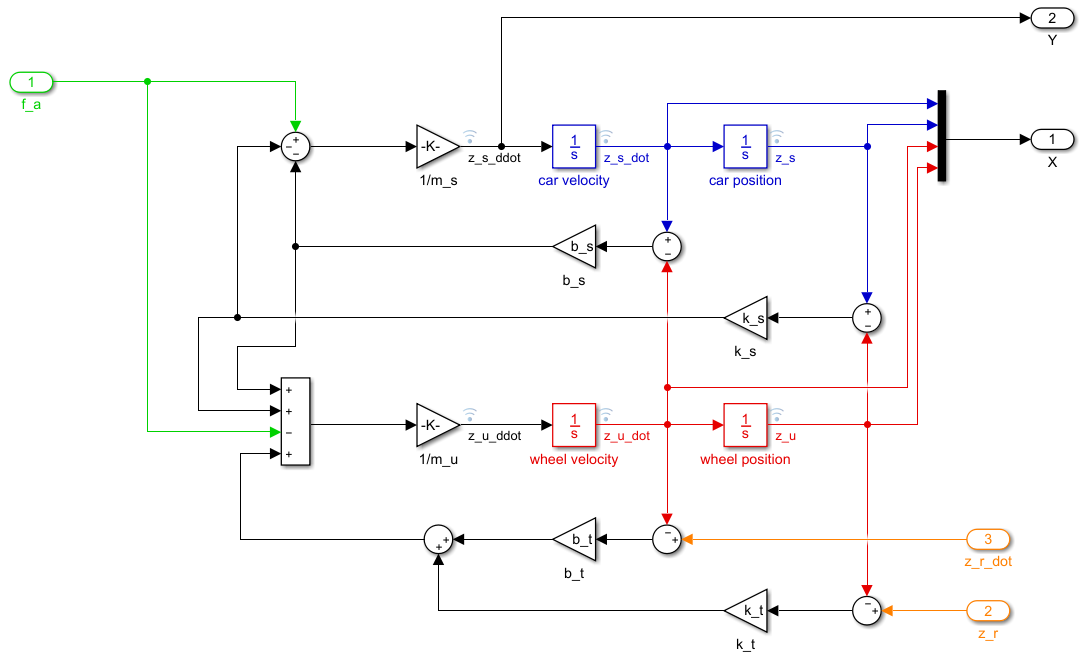

% Your solution goes here




**Problem 3 **Set the initial position of the sprung element to $z_s = -0.05\mathrm{m}$ and simulate the response of the system when all inputs are at zero and the other state variables retain the stationary value.

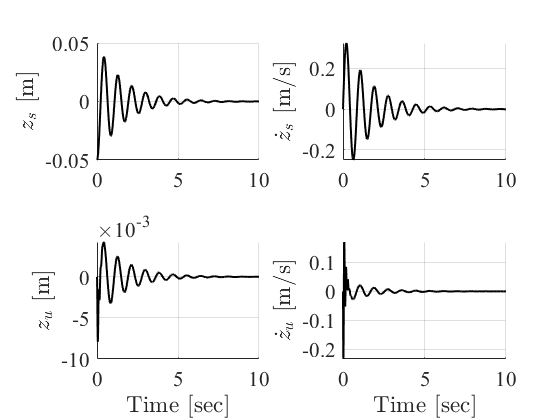

% Your solutions goes here

% To compute the zero input response we set the initial condition of the
% state vector to the specified value and then we run the simulation
% exploiting the simulink diagram.

SIM_TIME = 10;
x0 = [-0.05,0,0,0]'; % initial condition for the state vector
sim('QuarterCar_ActiveSusp_Simulink2019b',SIM_TIME,[],[]);

time_det = logsout.getElement('z_s').Values.Time;
z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;

figure, h1 = subplot(2,2,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s,'k','LineWidth',1.5)
ylabel('$z_s$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,2,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_dot,'k','LineWidth',1.5)
ylabel('$\dot{z}_s$ [m$/$s]','FontName','times','FontSize',16,'Interpreter','latex')
h3 = subplot(2,2,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_u,'k','LineWidth',1.5)
ylabel('$z_u$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
h4 = subplot(2,2,4); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_u_dot,'k','LineWidth',1.5)
ylabel('$\dot{z}_u$ [m$/$s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

**Problem 4 **Assess the open-loop characteristics of the

- vertical acceleration $\ddot{z}_s$

- tire deflection $(z_u-z_r)$

- suspension deflection $(z_s-z_u)$

in terms of largest deviation from the stationary state, decay rate and settling time when the system is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$.

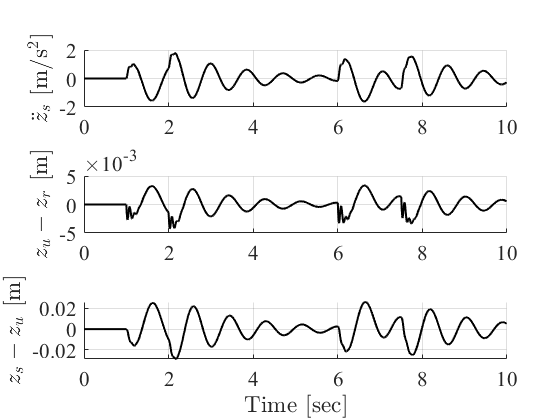

% Your solutions goes here

% Road profiles for open simulations (RG)
load road_profile.mat
time_det = time_det'; % column vector
z_r_det = z_r_det'; % column vector
% [t_det,z_r_det,z_r_dot_det] - deterministic road profile where t_det is the
% travelling time, z_r_det is the vertical road displacement and z_r_dot_det
% is the rate of change of the road profile.
% The profile has been generated for a car traveling with a forward
% speed of 40 km/h

SIM_TIME = time_det(end);
x0 = zeros(4,1); % remember to set the initial conditions to zero, since we are computing the zero state response
f_a = zeros(length(time_det),1); % control input set to zero since we are assessing the 
% system behaviour in reponse to the road disturance
sim('QuarterCar_ActiveSusp_Simulink2019b',SIM_TIME,[],[time_det f_a z_r_det z_r_dot_det])

% Plot the temporal behaviour of 
%   *   vertical accelaration
%   *   tire deflection
%   *   suspension deflection

z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_s_ddot = logsout.getElement('z_s_ddot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;

tire_defl = z_u - z_r_det;
susp_defl = z_s - z_u;

figure, h6 = subplot(3,1,1); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_ddot,'k','LineWidth',1.5)
ylabel('$\ddot{z}_s$ [m/s$^2$]','FontName','times','FontSize',16,'Interpreter','latex')
h7 = subplot(3,1,2); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,tire_defl,'k','LineWidth',1.5)
ylabel('$z_u -z_r$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h8 = subplot(3,1,3); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,susp_defl,'k','LineWidth',1.5)
ylabel('$z_s-z_u$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')


max_z_s_ddot = max(abs(z_s_ddot));
disp('The maximum peak of the vertical acceleration in open loop is [m/s^2]:')

The maximum peak of the vertical acceleration in open loop is [m/s^2]:


disp(max_z_s_ddot)

    1.7917




max_tire_defl = max(abs(tire_defl));
disp('The maximum peak of the tire deflection in open loop is [m]:')

The maximum peak of the tire deflection in open loop is [m]:


disp(max_tire_defl)

    0.0043




max_susp_defl = max(abs(susp_defl));
disp('The maximum peak of the suspension deflection in open loop is [m]:')

The maximum peak of the suspension deflection in open loop is [m]:


disp(max_susp_defl)

    0.0289



An estimate of the decay rate and settling time can be obtained through the analysis of the system eigenvalues

[wn,zeta] = damp(A) % the function damp computes the natural frequencies 

wn =    59.0183
   59.0183
    7.3723
    7.3723


zeta =     0.1685
    0.1685
    0.0836
    0.0836


% and damping ratios associated with the eigenvalues of the system 
% dynamical matrix A
T_osc = 2*pi./[wn(1) wn(3)] % periods of oscialltory modes

T_osc =     0.1065    0.8523


Two oscillatory modes characterize the state and output response of the system: one oscillation with period of approximately 0.1s, and a second oscillation with period of approximately 0.85s. These different oscillations are clearly visible from the plots of acceleration, tire and suspension deflection. The decay rate and settling time are determined by the oscillatory mode with the larger oscillation period, which is also associated with the smallest damping ratio ($\zeta = 0.0836$).

% Decay rate
alpha = -wn(3)*zeta(3) % this is the real part of the complex eigenvalue, which is also appearing in the exponent of the oscillatory eigenmode

alpha = -0.6162


% Settling time
t_set = 5*1/abs(alpha) % the settling time [s] is estimated as 5 times the time constant associated with the slow complex eigenvalue

t_set = 8.1137

**Problem 5 **Compute the eigenvalues of the system and asses the internal stability properties. Calculate the damping rato and natural frequency of each couple of complex poles.

% Your solutions goes here
lambda_A_ol = eig(A);
disp(lambda_A_ol)

  -9.9451 +58.1744i
  -9.9451 -58.1744i
  -0.6162 + 7.3465i
  -0.6162 - 7.3465i




disp('The real part of all four eigenvalues is negative, hence')

The real part of all four eigenvalues is negative, hence


disp('the system is internally asymptotically stable.')

the system is internally asymptotically stable.


% The damping ratios and the natural frequencies can be assessed using the
% function damp or throug the formulas:
% wn = sqrt(Re{lambda}^2 + Im{lambda}^2)
% zeta = -Re{lambda}/wn

[wn_A_ol,zeta_A_ol] = damp(A)

wn_A_ol =    59.0183
   59.0183
    7.3723
    7.3723


zeta_A_ol =     0.1685
    0.1685
    0.0836
    0.0836


wn_A_ol2 = sqrt(real(lambda_A_ol).^2+imag(lambda_A_ol).^2)

wn_A_ol2 =    59.0183
   59.0183
    7.3723
    7.3723


zeta_A_ol2 = -real(lambda_A_ol)./wn_A_ol2

zeta_A_ol2 =     0.1685
    0.1685
    0.0836
    0.0836


From this analysis we can see once again that the system has two under damped oscillatory modes. 

**Problem 6** Calculate the transfer function from the control input $f_a$ to the vertical acceleration of sprung mass $\ddot{z}_s$. Determine the position of the system poles and conclude about extenal stability.

**Solution** To compute the transfer function from the control input to the vertical acceleration of the sprung mass, we need to set such acceleration as an ouput of the linear system. To do that we can notice that the acceleration of the sprung mass is actually given by the second state equation. Therefore by setting the output matrix to


$$\mathbf{C} = \left[-\frac{k_s}{m_s} \,\,  -\frac{b_s}{m_s} \,\, \frac{k_s}{m_s} \,\, \frac{b_s}{m_s}\right]$$


we can generate the needed system output.

% Your solutions goes here
C = [-k_s/m_s -b_s/m_s k_s/m_s b_s/m_s];
[numG,denG] = ss2tf(A,[B Bv],C,zeros(1,2),1); % the first input is the control input

disp('The transfer function from control input f_a to acceleration of the sprung mass is')

The transfer function from control input f_a to acceleration of the sprung mass is


minreal(tf(numG,denG)) % the minreal function ensures that zero-pole cancellations are done


ans =
 
                                        
  -0.04433 s^3 - 1.833 s^2 - 22.12 s    
                                        
                                 - 779.1
                                        
  --------------------------------------
                                        
  s^4 + 21.12 s^3 + 3562 s^2 + 5374 s   
                                        
                              + 1.893e05
                                        
 
Continuous-time transfer function.



**Problem 7** Select a suitable sampling time $T_s$ and discretize the continuous time model obtained in Problem 1.

**Solution** Since we have no control requirements the selection of the sampling time is solely based on the dynamic characteristics of the system. In particular we should consider the smallest period of oscillation of the system and take the sampling time to be at least 10 times as fast. The validity of the chosen sampling time could be verified e.g. by simulating the continuous time and the discrete time systems subject to the same input or initial conditions and comparing the obtained responses.

% Your solutions goes here
% In Problem 4 the periods of oscillation T_osc were already computed. So
% we can take the smallest of the found values and divide that by e.g. 10

min_T_osc = min(T_osc);
Ts = min_T_osc/10;
disp('The sampling time is')

The sampling time is


disp(Ts)

    0.0106




% The discrete time linear model is then found by applying the c2d function
[F,G] = c2d(A,B,Ts);
[~,Gv] = c2d(A,Bv,Ts);

susp_ss_dt = ss(F,[G Gv],C,zeros(1,2),Ts) % generate the discrete time state space model


susp_ss_dt =
 
  A = 
              x1         x2         x3
   x1     0.9967    0.01055   0.002325
   x2    -0.6081     0.9814     0.3312
   x3    0.01879  0.0005399     0.8215
   x4      3.285     0.1011     -31.31
 
              x4
   x1  8.887e-05
   x2    0.01665
   x3   0.008992
   x4     0.6461
 
  B = 
               u1          u2
   x1    2.24e-07   7.868e-09
   x2    4.12e-05   2.222e-06
   x3  -1.273e-06   1.281e-06
   x4  -0.0002226   0.0002248
 
  C = 
           x1      x2      x3      x4
   y1  -60.74  -1.523   60.74   1.523
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.010646 seconds
Discrete-time state-space model.

